## With or without consumption estimation

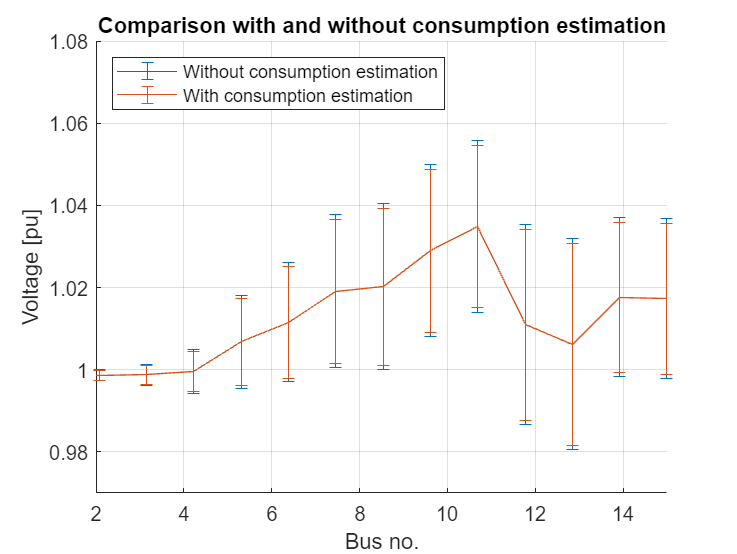

clc
clear
load("Data\SimRes_Hybrid.mat")
MeanVal(:,1) = mean(X(1:14,:),2);
VarVal(:,1) = var(X(1:14,:)')';
load('Data\SimRes_Hybrid_est.mat')
MeanVal(:,2) = mean(X(1:14,:),2);
VarVal(:,2) = var(X(1:14,:)')';

busNo = linspace(1,15,14);
figure()
hold on
errorbar(busNo,MeanVal(:,1),sqrt(VarVal(:,1)))
errorbar(busNo,MeanVal(:,2),sqrt(VarVal(:,2)))
xlim([2 15])
ylim([0.97 1.08])
xlabel("Bus no.")
ylabel("Voltage [pu]")
title("Comparison with and without consumption estimation")
legend("Without consumption estimation", "With consumption estimation",Location="northwest")
hold off
grid on
set(gcf, 'PaperUnits', 'centimeters');
set(gcf, 'PaperPosition', [0 0 16 9]);
saveas(gcf,'Figure/Comparison_Hybrid_ConsumptionEst','epsc')

## With or without deviation in historical data

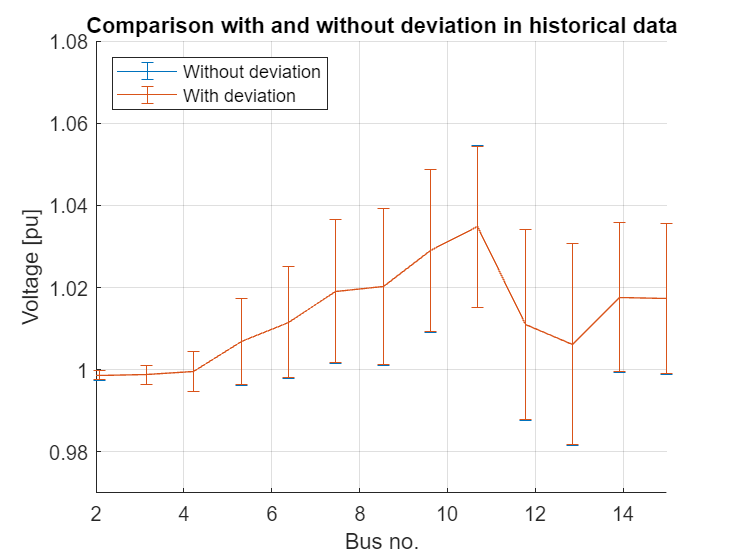

clc
clear
load("Data\SimRes_Hybrid_est.mat")
MeanVal(:,1) = mean(X(1:14,:),2);
VarVal(:,1) = var(X(1:14,:)')';
load('Data\SimRes_Hybrid_est_deviation.mat')
MeanVal(:,2) = mean(X(1:14,:),2);
VarVal(:,2) = var(X(1:14,:)')';

busNo = linspace(1,15,14);
figure()
hold on
errorbar(busNo,MeanVal(:,1),sqrt(VarVal(:,1)))
errorbar(busNo,MeanVal(:,2),sqrt(VarVal(:,2)))
xlim([2 15])
ylim([0.97 1.08])
xlabel("Bus no.")
ylabel("Voltage [pu]")
title("Comparison with and without deviation in historical data")
legend("Without deviation", "With deviation",Location="northwest")
hold off
grid on
set(gcf, 'PaperUnits', 'centimeters');
set(gcf, 'PaperPosition', [0 0 16 9]);
saveas(gcf,'Figure/Comparison_Hybrid_ConsumptionEstDeviation','epsc')

## With more actuation

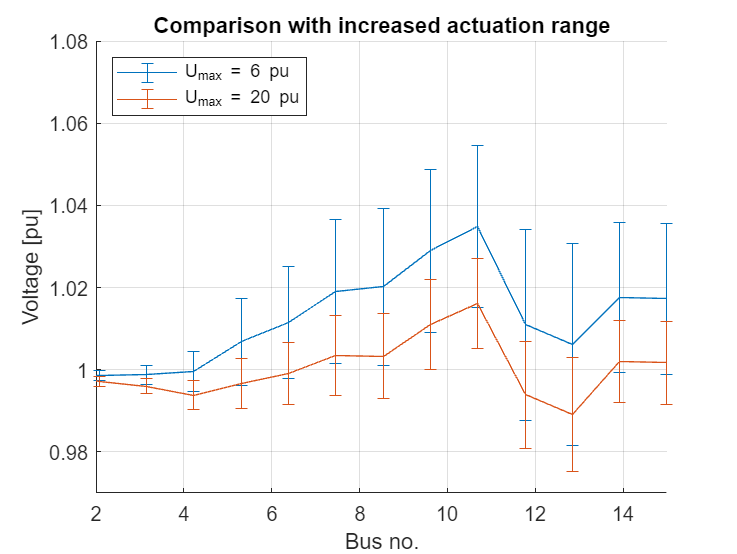

clc
clear
load('Data\SimRes_Hybrid_est.mat')
MeanVal(:,1) = mean(X(1:14,:),2);
VarVal(:,1) = var(X(1:14,:)')';
load("Data\SimRes_Hybrid_More_Actuation.mat")
MeanVal(:,2) = mean(X(1:14,:),2);
VarVal(:,2) = var(X(1:14,:)')';

busNo = linspace(1,15,14);
figure()
hold on
errorbar(busNo,MeanVal(:,1),sqrt(VarVal(:,1)))
errorbar(busNo,MeanVal(:,2),sqrt(VarVal(:,2)))
xlim([2 15])
ylim([0.97 1.08])
xlabel("Bus no.")
ylabel("Voltage [pu]")
title("Comparison with increased actuation range")
legend("U_{max} = 6 pu", "U_{max} = 20 pu",Location="northwest")
hold off
grid on
set(gcf, 'PaperUnits', 'centimeters');
set(gcf, 'PaperPosition', [0 0 16 9]);
saveas(gcf,'Figure/Comparison_More_Actuation','epsc')

## With more PV EQ spaced

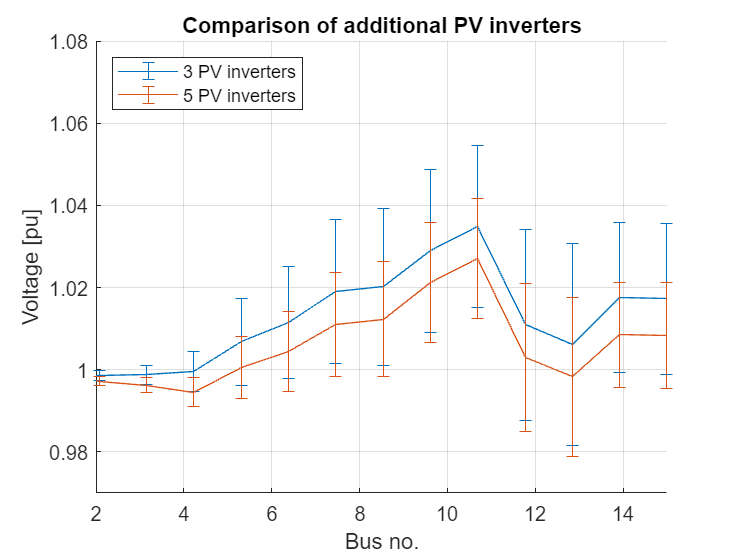

clc
clear
load('Data\SimRes_Hybrid_est.mat')
MeanVal(:,1) = mean(X(1:14,:),2);
VarVal(:,1) = var(X(1:14,:)')';
load("Data\SimRes_Hybrid_more_pv_random.mat")
MeanVal(:,2) = mean(X(1:14,:),2);
VarVal(:,2) = var(X(1:14,:)')';

busNo = linspace(1,15,14);
figure()
hold on
errorbar(busNo,MeanVal(:,1),sqrt(VarVal(:,1)))
errorbar(busNo,MeanVal(:,2),sqrt(VarVal(:,2)))
xlim([2 15])
ylim([0.97 1.08])
xlabel("Bus no.")
ylabel("Voltage [pu]")
title("Comparison of additional PV inverters")
legend("3 PV inverters", "5 PV inverters",Location="northwest")
hold off
grid on
set(gcf, 'PaperUnits', 'centimeters');
set(gcf, 'PaperPosition', [0 0 16 9]);
saveas(gcf,'Figure/Comparison_More_PV_EQ_spaced','epsc')

## With more PV EQ spaced

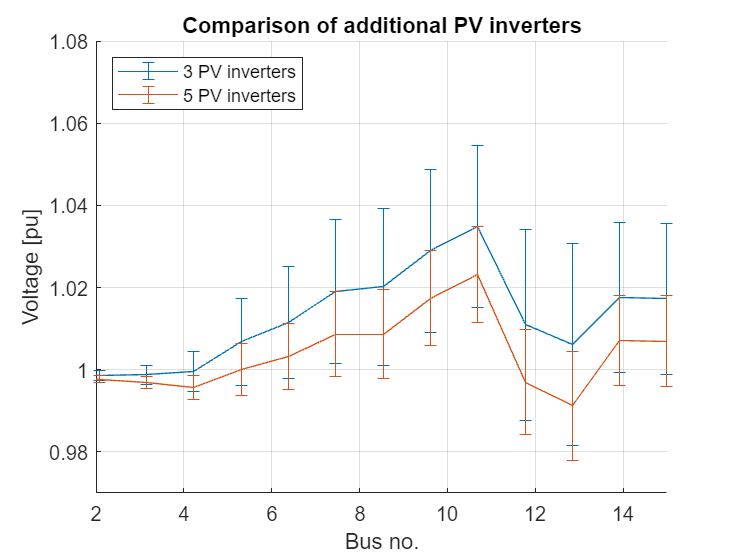

clc
clear
load('Data\SimRes_Hybrid_est.mat')
MeanVal(:,1) = mean(X(1:14,:),2);
VarVal(:,1) = var(X(1:14,:)')';
load("Data\SimRes_Hybrid_more_pv_optimal.mat")
MeanVal(:,2) = mean(X(1:14,:),2);
VarVal(:,2) = var(X(1:14,:)')';

busNo = linspace(1,15,14);
figure()
hold on
errorbar(busNo,MeanVal(:,1),sqrt(VarVal(:,1)))
errorbar(busNo,MeanVal(:,2),sqrt(VarVal(:,2)))
xlim([2 15])
ylim([0.97 1.08])
xlabel("Bus no.")
ylabel("Voltage [pu]")
title("Comparison of additional PV inverters")
legend("3 PV inverters", "5 PV inverters",Location="northwest")
hold off
grid on
set(gcf, 'PaperUnits', 'centimeters');
set(gcf, 'PaperPosition', [0 0 16 9]);
saveas(gcf,'Figure/Comparison_More_PV','epsc')

## Placement of new PV

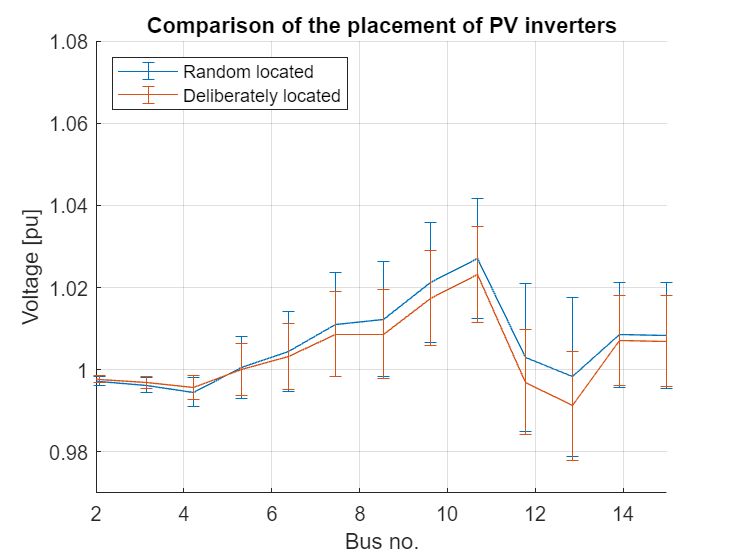

clc
clear
load("Data\SimRes_Hybrid_more_pv_random.mat")
MeanVal(:,1) = mean(X(1:14,:),2);
VarVal(:,1) = var(X(1:14,:)')';
load("Data\SimRes_Hybrid_more_pv_optimal.mat")
MeanVal(:,2) = mean(X(1:14,:),2);
VarVal(:,2) = var(X(1:14,:)')';

busNo = linspace(1,15,14);
figure()
hold on
errorbar(busNo,MeanVal(:,1),sqrt(VarVal(:,1)))
errorbar(busNo,MeanVal(:,2),sqrt(VarVal(:,2)))
xlim([2 15])
ylim([0.97 1.08])
xlabel("Bus no.")
ylabel("Voltage [pu]")
title("Comparison of the placement of PV inverters")
legend("Random located","Deliberately located",Location="northwest")
hold off
grid on
set(gcf, 'PaperUnits', 'centimeters');
set(gcf, 'PaperPosition', [0 0 16 9]);
saveas(gcf,'Figure/Comparison_PV_Placement','epsc')

## Grid search comparison of 1 additional PV

clc
clear
possibleLocations = [2,3,4,5,6,8,9,11,12,13,14];
for e = 1:length(possibleLocations)
    load(strcat("Data\SimRes_Hybrid_grid_",num2str(possibleLocations(e))))
    MeanVal(:,e) = mean(X(1:14,:),2);
    VarVal(:,e) = var(X(1:14,:)')';
end

[val, indexMean] = min(mean(MeanVal) - 1)

val = 0.0071

indexMean = 9

[val, indexVar] = min(sum(VarVal,1))

val = 0.0022

indexVar = 9

possibleLocations(indexVar)

ans = 12

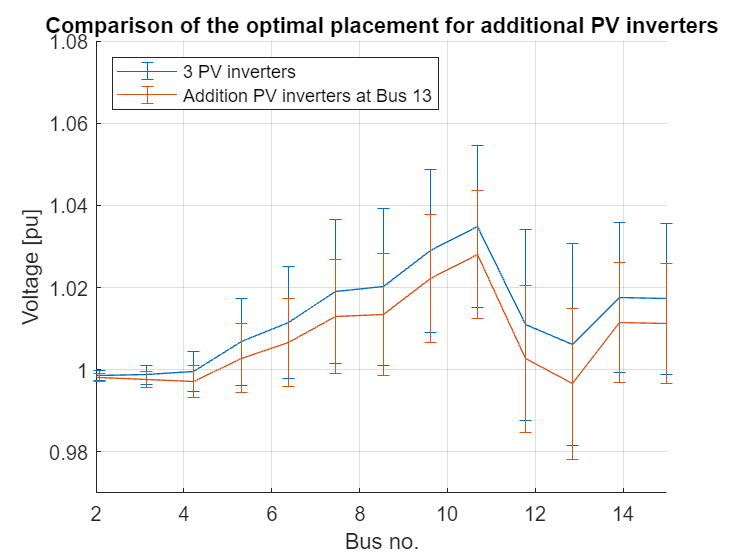


clear MeanVal VarVal
load("Data\SimRes_Hybrid_est.mat")
MeanVal(:,1) = mean(X(1:14,:),2);
VarVal(:,1) = var(X(1:14,:)')';
load(strcat("Data\SimRes_Hybrid_grid_",num2str(possibleLocations(indexVar))))

MeanVal(:,2) = mean(X(1:14,:),2);
VarVal(:,2) = var(X(1:14,:)')';
busNo = linspace(1,15,14);
figure()
hold on
errorbar(busNo,MeanVal(:,1),sqrt(VarVal(:,1)))
errorbar(busNo,MeanVal(:,2),sqrt(VarVal(:,2)))
xlim([2 15])
ylim([0.97 1.08])
xlabel("Bus no.")
ylabel("Voltage [pu]")
title("Comparison of the optimal placement for additional PV inverters")
legend("3 PV inverters", "Addition PV inverters at Bus 13",Location="northwest")
hold off
grid on
set(gcf, 'PaperUnits', 'centimeters');
set(gcf, 'PaperPosition', [0 0 16 9]);
saveas(gcf,'Figure/Comparison_GridSearch','epsc')

## Full PV

clc
clear
load("Data\SimulationResultHybridFullPV.mat")

Error using load
Unable to find file or directory 'Data\SimulationResultHybridFullPV.mat'.

MeanVal(:,1) = mean(X(1:14,:),2);
VarVal(:,1) = var(X(1:14,:)')';
load("Data\SimulationResultHybridRetard.mat")
MeanVal(:,2) = mean(X(1:14,:),2);
VarVal(:,2) = var(X(1:14,:)')';

busNo = linspace(1,15,14);
figure()
hold on
errorbar(busNo,MeanVal(:,1),sqrt(VarVal(:,1)))
errorbar(busNo,MeanVal(:,2),sqrt(VarVal(:,2)))
xlim([2 15])
ylim([0.97 1.08])
xlabel("Bus no.")
ylabel("Voltage [pu]")
title("Comparison of the mean and std")
legend("Full", "Retard",Location="northwest")
hold off
grid on
set(gcf, 'PaperUnits', 'centimeters');
set(gcf, 'PaperPosition', [0 0 16 9]);
saveas(gcf,'Figure/Comparison_PV_Retard','epsc')